clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=1;
gamma=0.5;
ome=2;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind1= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1= 2*mean(diff(t(ind1(length(ind1)-10:length(ind1)-1))))

period1 = 3.1365

omega1=2*pi/period1

omega1 = 2.0033

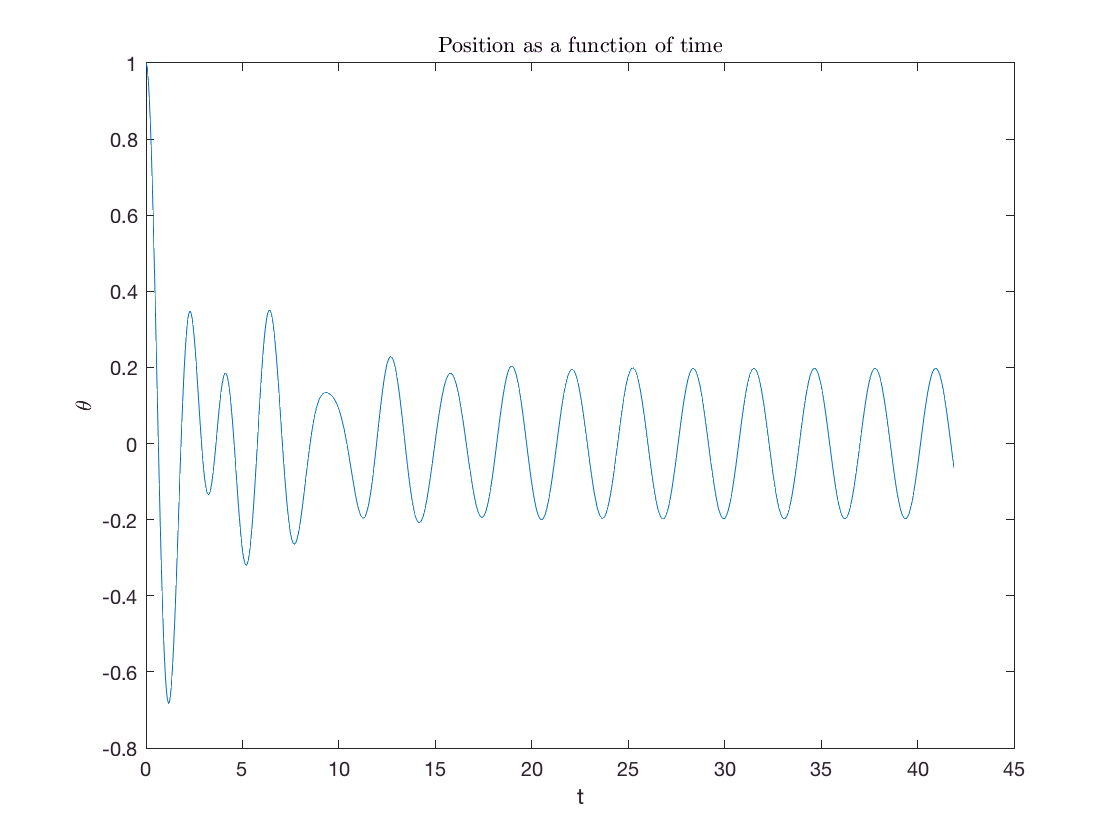

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

thetad0=1;
theta0=0;
ome=2;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind2= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period2= 2*mean(diff(t(ind2(length(ind2)-10:length(ind2)-1))))

period2 = 3.1383

omega2=2*pi/period2

omega2 = 2.0021

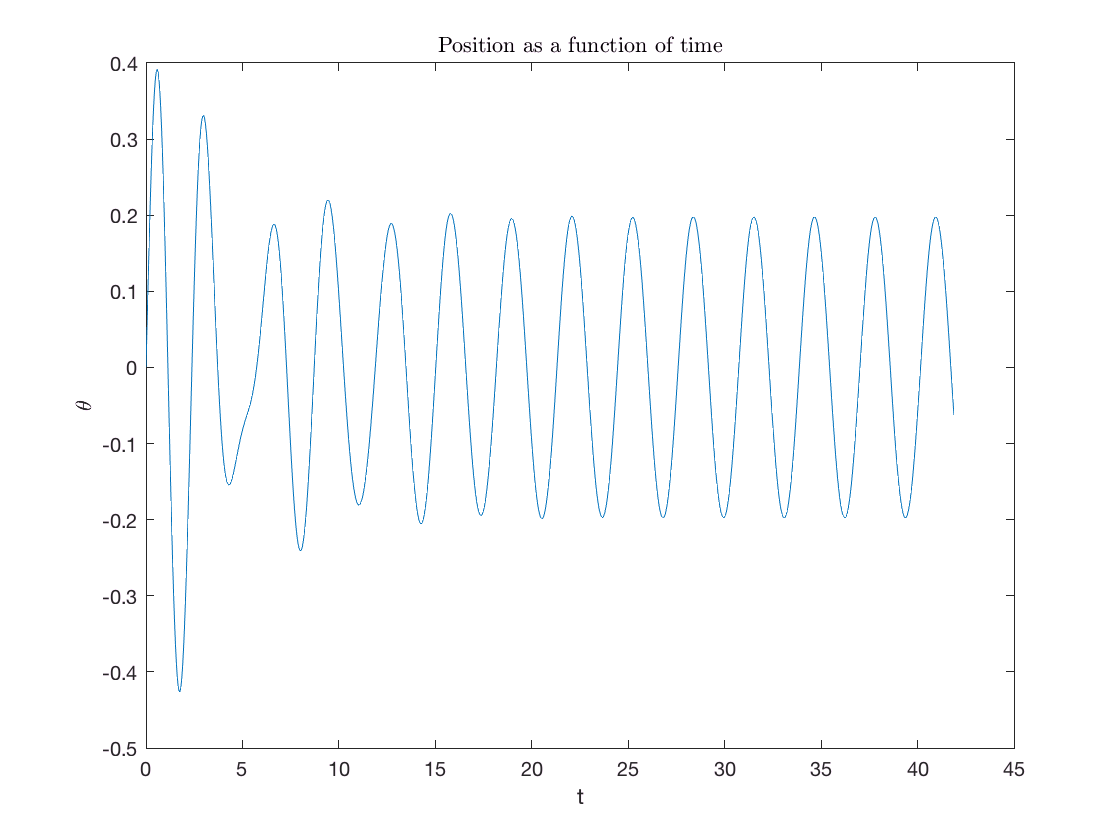

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

thetad0=0;
theta0=1;
ome=1;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind3= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period3= 2*mean(diff(t(ind3(length(ind3)-10:length(ind3)-1))))

period3 = 6.2734

omega3=2*pi/period3

omega3 = 1.0016

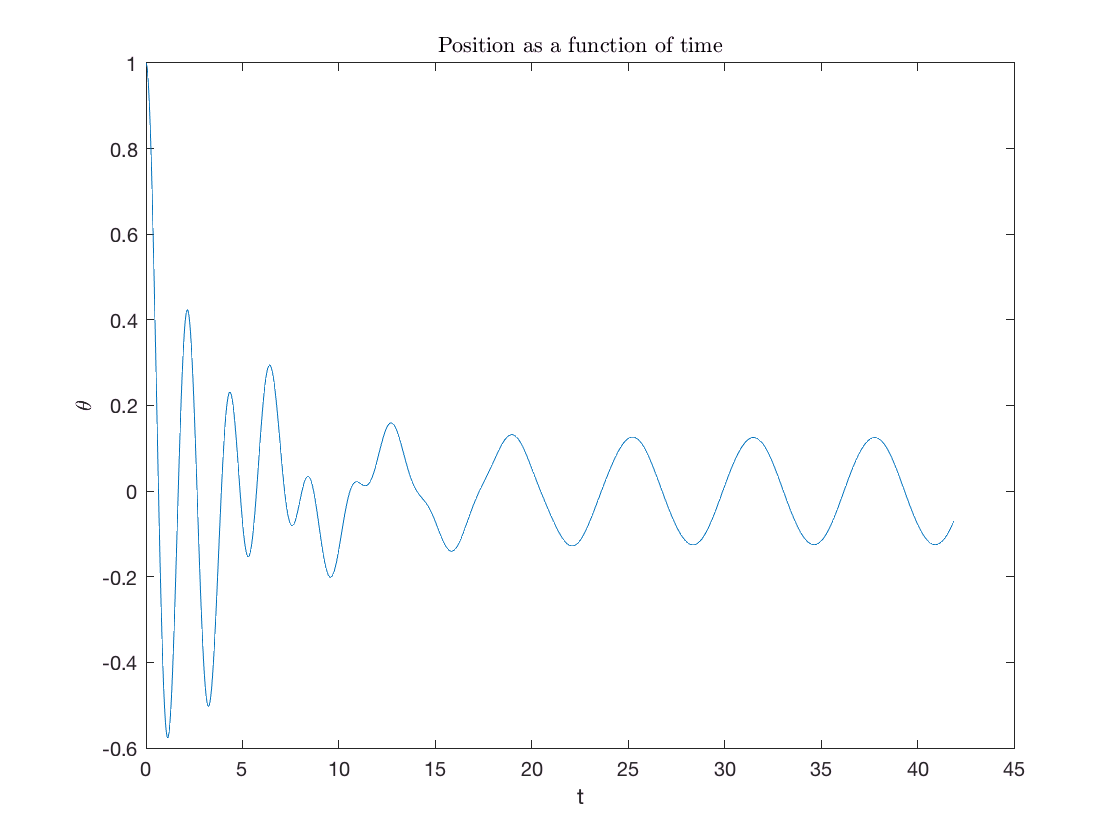

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

thetad0=0;
theta0=1;
ome=4;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind4= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period4= 2*mean(diff(t(ind4(length(ind4)-10:length(ind4)-1))))

period4 = 1.5718

omega4=2*pi/period4

omega4 = 3.9974

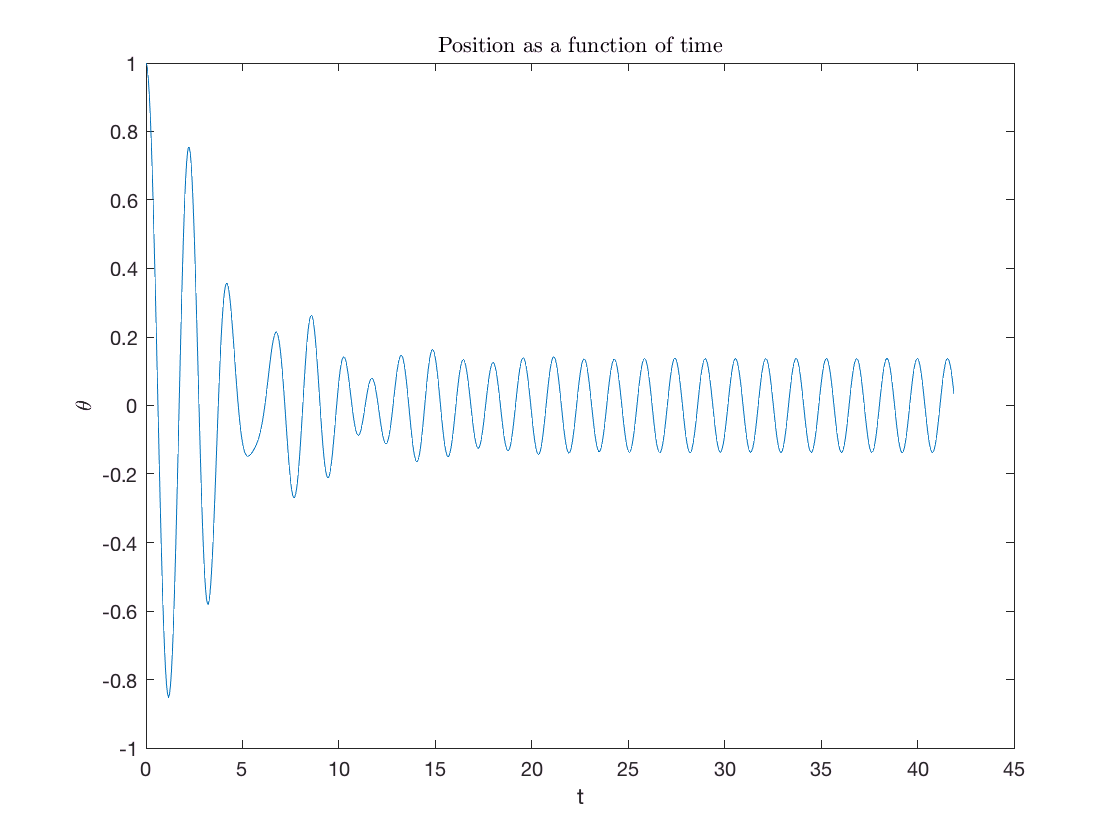

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

i=0;
j=0;
for gamma=[0.5,1.5]
    i=i+1
    for ome=[0, 1, 2, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4]
        j=j+1;
        delta(i,j)=